# Equacions diferencials (II)

#### PVI

f = @(t,y)2/t*y+t.^2*exp(t);  
a = 1;  alpha = 0;    % y(a) = alpha
b = 2;  % y(b) = ...

Solució analítica

Y = @(t)t.^2.*(exp(t)-exp(1)); 

# Metode d'Euler

h = 0.1;
[t1, YE] = Euler(f, a, b, h, alpha);

w =      0


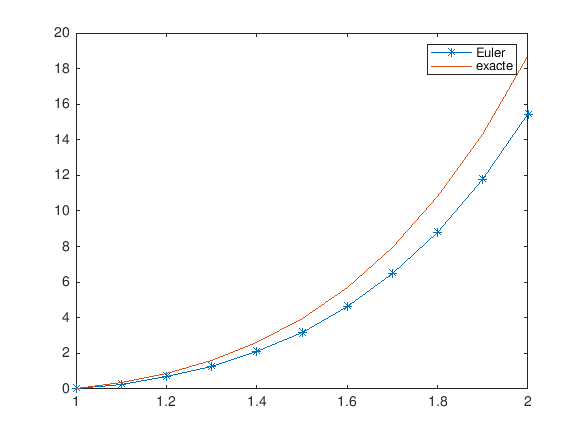

plot(t1, YE, '-*', t1, Y(t1))
legend('Euler', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]'

ans =             1            0            0            0
          1.1      0.27183      0.34592     0.074092
          1.2      0.68476      0.86664      0.18189
          1.3        1.277       1.6072      0.33024
          1.4       2.0935       2.6204      0.52681
          1.5       3.1874       3.9677      0.78022
          1.6       4.6208        5.721       1.1001
          1.7       6.4664       7.9639       1.4975
          1.8       8.8091       10.794       1.9845
          1.9       11.748       14.323       2.5751


# Euler Millorat

h = 0.1;
[t1, YE] = EulerMill(f, a, b, h, alpha);

w =      0


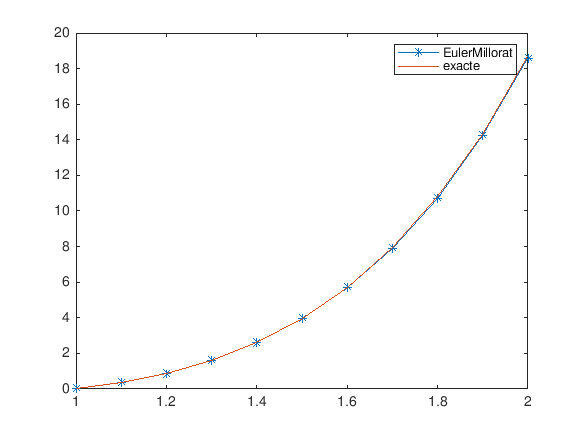

plot(t1, YE, '-*', t1, Y(t1))
legend('EulerMillorat', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]'

ans =             1            0            0            0
          1.1      0.34238      0.34592    0.0035421
          1.2      0.85831      0.86664     0.008328
          1.3       1.5927       1.6072     0.014465
          1.4       2.5983       2.6204     0.022061
          1.5       3.9364       3.9677     0.031222
          1.6       5.6789        5.721     0.042054
          1.7       7.9092       7.9639     0.054664
          1.8       10.724       10.794     0.069158
          1.9       14.237       14.323      0.08564


# Euler Modificat

h = 0.1;
[t1, YE] = EulerMod(f, a, b, h, alpha);

w =      0


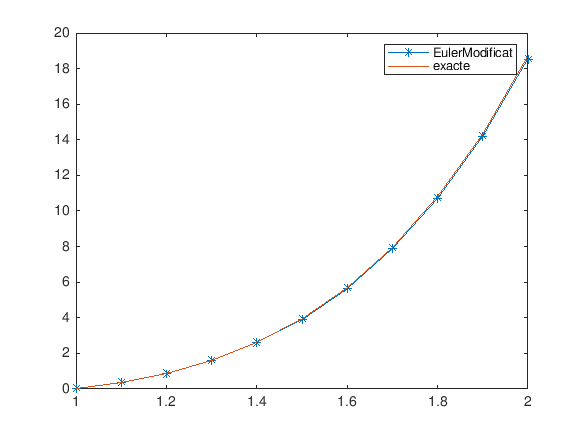

plot(t1, YE, '-*', t1, Y(t1))
legend('EulerModificat', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]'

ans =             1            0            0            0
          1.1      0.34094      0.34592    0.0049754
          1.2      0.85491      0.86664     0.011733
          1.3       1.5867       1.6072     0.020507
          1.4       2.5888       2.6204     0.031552
          1.5       3.9225       3.9677     0.045141
          1.6       5.6594        5.721     0.061575
          1.7       7.8827       7.9639     0.081179
          1.8       10.689       10.794      0.10431
          1.9       14.192       14.323      0.13137


# RK4

h = 0.1;
[t1, YE] = RK4(f, a, b, h, alpha);

w =      0


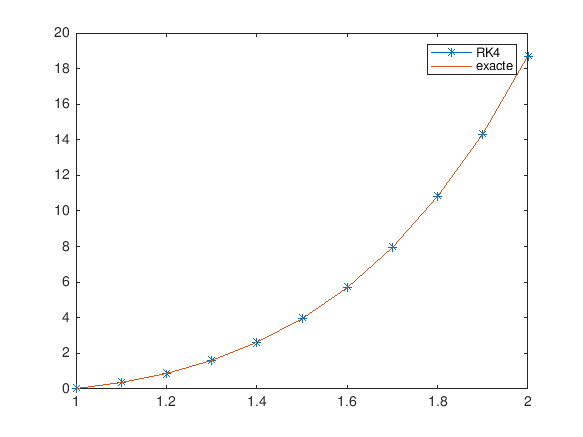

plot(t1, YE, '-*', t1, Y(t1))
legend('RK4', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]

ans =             1          1.1          1.2          1.3          1.4          1.5          1.6          1.7          1.8          1.9            2
            0      0.34591      0.86662       1.6072       2.6203       3.9676       5.7209       7.9638       10.794       14.323       18.683
            0      0.34592      0.86664       1.6072       2.6204       3.9677        5.721       7.9639       10.794       14.323       18.683
            0   9.5892e-06   2.0843e-05   3.3731e-05   4.8245e-05   6.4396e-05   8.2201e-05   0.00010169   0.00012288   0.00014581   0.00017051


#### Interpolació Lineal

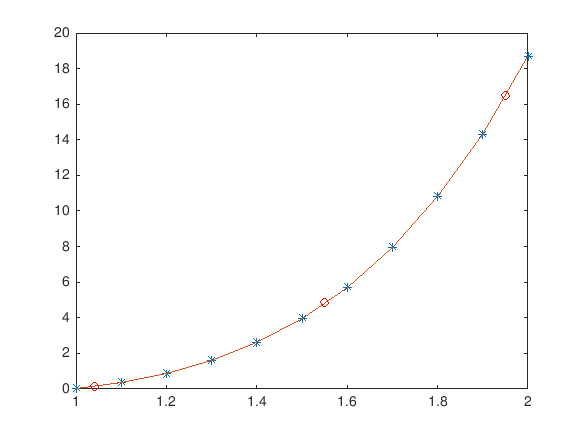

v1 = interp1(t1,YE, 1.04);
v2 = interp1(t1,YE, 1.55);
v3 = interp1(t1,YE, 1.95);
plot(t1, YE, '-*', t1, Y(t1), 1.04, v1, 'ro', 1.55, v2, 'ro', 1.95, v3, 'ro')